# Gráficos de la Boya de Gando

## Importar archivo y crear tablas para cada parámetro

gando = importGandoPlots("C:\Users\usuario\Desktop\Datos_Boya_Gando\gando.xlsx");

cyc = gando(:, 1:3);
sb = gando(:, 4:6);
rawOptode = gando(:, 8:12);
co = gando(: ,14:15);
phDef = gando(:, 16:18);

% Eliminar filas vacías
nanCyc = isnan(cyc.Fluorescece);
cyc(nanCyc, :) = [];

nanSb = isnan(sb.SST);
sb(nanSb, :) = [];

nanOp = isnan(rawOptode.Oxy);
rawOptode(nanOp, :) = [];

nanCo = isnan(co.pCO2);
co(nanCo, :) = [];

nanPh = isnan(phDef.pHTis);
phDef(nanPh, :) = [];

badSal = find(sb.SSS < 36);
badT = find(sb.SST > 26 | sb.SST < 17);
badCO2 = find(co.pCO2 > 500| co.pCO2 < 360);
disp(numel(badSal) + " bad salinity values.")

0 bad salinity values.


disp(numel(badT) + " bad temperature values.")

0 bad temperature values.


disp(numel(badCO2) + " bad CO2 values.")

13 bad CO2 values.


% pCO2: 16 jul-31 jul 6332- 6457
% 26 sept-9 oct 6894-7004 
% 13 feb-23 feb 7435-7497
% 11 nov - 3 jan 4373-4793
% 27 jul-25 sep 987-1463
% o2: 1 aug-31 aug 1031-1277

co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(6332:6457));
co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(6894:7004));
co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(7435:7497));
co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(4373:4793));
co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(987:1463));
co.pCO2 = standardizeMissing(co.pCO2, co.pCO2(badCO2));
sb.SSS = standardizeMissing(sb.SSS, sb.SSS(badSal));
sb.SST = standardizeMissing(sb.SST, sb.SST(badT));
rawOptode.O2Concentration = standardizeMissing(rawOptode.O2Concentration, rawOptode.O2Concentration(1031:1277));

## Gráficos individuales

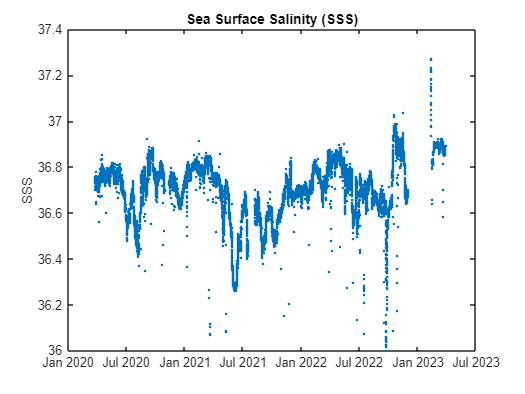

plot(sb.DateMicrocatSIP, sb.SSS, ".")
title("Sea Surface Salinity (SSS)")
ylabel("SSS")

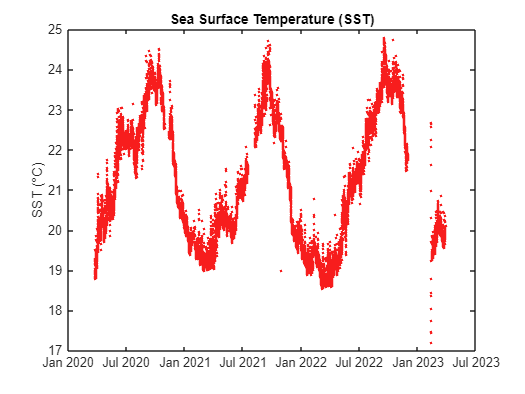

%ylim([35.5, 37.5])

plot(sb.DateMicrocatSIP, sb.SST, ".",  "Color", "#f71d1d")
ylabel("SST (°C)")
title("Sea Surface Temperature (SST)")

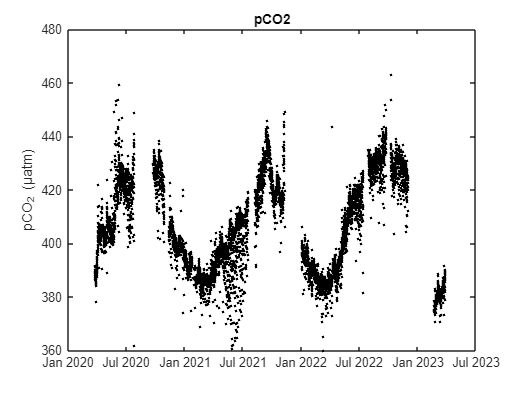

%ylim([16, 26])

plot(co.DateProOceanus, co.pCO2, "k.")
title("pCO2")
ylabel("pCO_{2} (µatm)")

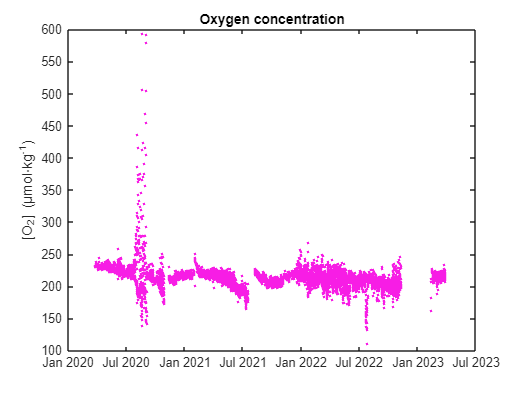

%ylim([300, 480])

plot(rawOptode.DateOptode, rawOptode.O2Concentration, ".", "Color", "#f71de5")
title("Oxygen concentration")
ylabel("[O_{2}] (µmol⋅kg^{-1})")

## Gráficos apilados

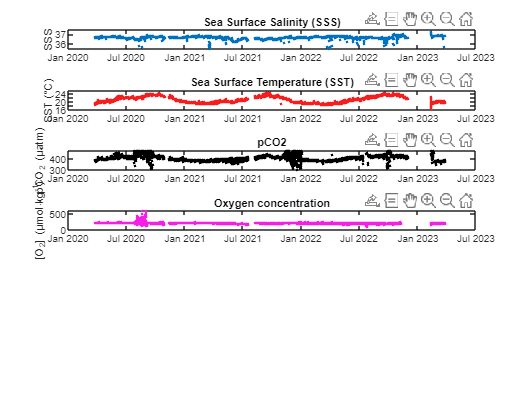

tiledlayout(6, 1)

% ax1 = nexttile;
% 
% plot(ax1, cyc.DateCyc, cyc.Chlorofila, "g.")
% title("Chlorophyll")
% ylabel("Chl─a (µg⋅l^{-1})")

ax2 = nexttile;

plot(ax2, sb.DateMicrocatSIP, sb.SSS, ".")
title("Sea Surface Salinity (SSS)")
ylabel("SSS")
ylim([35.5, 37.5])

ax3 = nexttile;

plot(ax3, sb.DateMicrocatSIP, sb.SST, ".",  "Color", "#f71d1d")
ylabel("SST (°C)")
title("Sea Surface Temperature (SST)")
ylim([16, 26])

ax4 = nexttile;

plot(ax4, co.DateProOceanus, co.pCO2, "k.")
title("pCO2")
ylabel("pCO_{2} (µatm)")
ylim([300, 480])

ax5 = nexttile;

plot(ax5, rawOptode.DateOptode, rawOptode.O2Concentration, ".", "Color", "#f71de5")
title("Oxygen concentration")
ylabel("[O_{2}] (µmol⋅kg^{-1})")


% ax6 = nexttile;
% 
% plot(ax6, phDef.DateSamipH, phDef.pHTis, ".", "Color", "blue")
% title("pH")
% ylim([7.9, 8.3])